# **FSIM (Functional SIMulator)**

**per ****f-HDGM**** e ****fp-HDGM**

Parametri da impostare:

- $\rho \ [1\times1]$;

- $\mathbf{c}_{\epsilon} \ [p_{\epsilon}\times 1]$;

- 
$$\mathbf{C}_{\beta} \ [b\times p_{\beta}]$$


- $\Sigma_0 \ [n\cdot p_z\times n\cdot p_z]$;

- $\mathbf{\mu}_0 \ [n\cdot p_z\times 1]$;

- $\mathbf{G} \ [p_z\times p_z]$;

- 
$$\mathbf{V} \ [p_z\times p_z]$$


- $\mathbf{\theta} \ [p_z\times 1]$;

- $n$, $q$, $b$ e $T$

addpath ..\'D-STEM v2.1'\Src\
clear all %#ok<CLALL> 
clc
rng('default')

#### **Scelta dei punti**

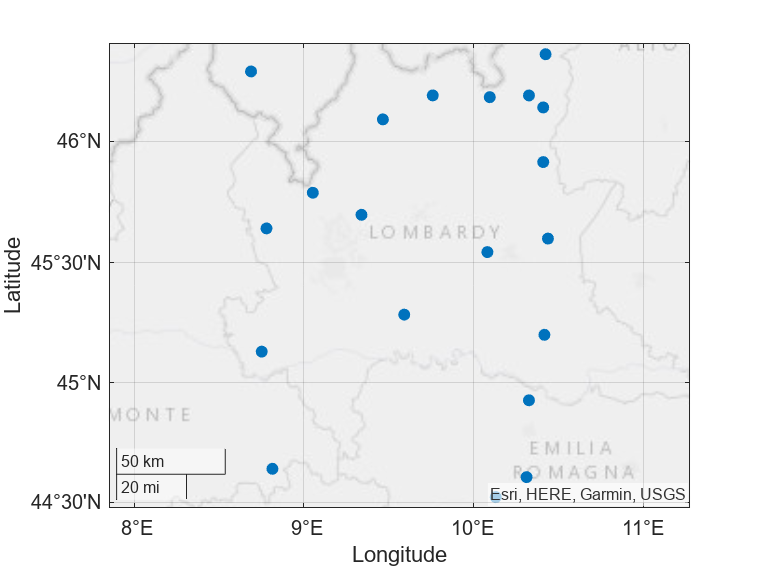

n = 20;
points = FSIM.get_points(n);
geoscatter(points, "Latitude", "Longitude", "filled")

#### Impostazione dei parametri

rng('default')

q = 24;
T = 365;
params.rho = 10;
n_basis.p_eps = 5;
n_basis.p_beta = 7;
n_basis.p_z = 7;

b = 2;
X = cell(T, 1);
for t=1:T
    X_t = ones(q*n, 2);
    for i=2:b
        X_t(:, 2) = randi(100, q*n, 1);
    end
    X{t} = X_t;
end

obj = FSIM(points, q, T, "NumBasis", n_basis, "Parameters", params);

FSIM (Functional SIMulator)
 
Authors: 
- Lorenzo LEONI
- Nicola ZAMBELLI
 
Dimensions: 
- n, q, b and T: [20 24 1 365]
- p_eps, p_beta and p_z: [5 7 7]
 
Parameters set: 
- rho: 10
- c_eps: [21   -0.0664489    -0.193816      1.22426    -0.304687]
- c_beta_1: [46  25  49  33  56  64  59]
- diag_G: [0.45398     0.50623     0.63056     0.20169     0.20303     0.16564     0.94144]
- diag_V: [2  5  5  2  8  7  8]
- theta: [36  36  36  36  36  36  36]


#### Avvio della/e simulazione/i

rng('default')
obj = obj.run(10);

Running simulation/s: 
- sim. 1 of 10 done.
- sim. 2 of 10 done.
- sim. 3 of 10 done.
- sim. 4 of 10 done.
- sim. 5 of 10 done.
- sim. 6 of 10 done.
- sim. 7 of 10 done.
- sim. 8 of 10 done.
- sim. 9 of 10 done.
- sim. 10 of 10 done.


**NB**: si ricorda che le osservazioni $Y_{sim}$ sono impilate prima per $q$, poi per $n$ (fissato $q$, viene espresso il valore di $y$ assunto presso le diverse $n$ stazioni).

#### Formattazione dei dati per rispettare la sintassi di D-STEM

data = obj.format_data;

Running data formatting: 
- dataset 1 of 10 done.
- dataset 2 of 10 done.
- dataset 3 of 10 done.
- dataset 4 of 10 done.
- dataset 5 of 10 done.
- dataset 6 of 10 done.
- dataset 7 of 10 done.
- dataset 8 of 10 done.
- dataset 9 of 10 done.
- dataset 10 of 10 done.


#### Validazione dei modelli spazio-temporali

Model type definition

o_modeltype = stem_modeltype('f-HDGM');
if obj.params.rho == 0
    o_modeltype.flag_potential = false;
else
    o_modeltype.flag_potential = true;
end

Basis configuration

input_fda.spline_type = 'Fourier';
input_fda.spline_range = [0 q];
input_fda.spline_nbasis_z = n_basis.p_z;
input_fda.spline_nbasis_beta = n_basis.p_beta; 
input_fda.spline_nbasis_sigma = n_basis.p_eps;
o_fda = stem_fda(input_fda);

Input data

input_data.stem_modeltype = o_modeltype;
input_data.data_table = data{1};
input_data.stem_fda = o_fda;
o_data = stem_data(input_data);

 
**********************************************
*   Data description of stem_varset object   *
**********************************************
Maximum number of observations per profile: q=24
 
Number of spatial locations: n=20
 
Number of time steps: T=365
 
Generating data matrices...
Generation ended.
Looking for duplicated sites...
Operation ended.


Input parameters

o_par = stem_par(o_data, 'exponential');
o_model = stem_model(o_data, o_par);

Generating data matrices...
Generation ended.


n_basis = o_fda.get_basis_number;

o_par.beta = o_model.get_beta0();
o_par.sigma_eps = o_model.get_coe_log_sigma_eps0();
o_par.theta_z = ones(1,n_basis.z)*40;
o_par.G = diag(ones(n_basis.z,1)*0.5);
o_par.v_z = eye(n_basis.z)*2;

if obj.params.rho ~= 0
    o_par.rho = 10;
end

o_model.set_initial_values(o_par);

Model estimation

% EM parameters
o_EM_options = stem_EM_options();
o_EM_options.exit_tol_par = 0.0001; 
o_EM_options.exit_tol_loglike = 0.0001; 
o_EM_options.max_iterations = 200;

% EM estimation
o_model.EM_estimate(o_EM_options);

Generating point distance matrices...
Generation ended.
 
**********************
*   D-STEM version   *
**********************
 
Model estimation is performed using D-STEM v2
 
******************************
*   Brief data description   *
******************************
Number of variables: q=24
 
Point variables:
sum of points for each variable: Nq=480
sum of sites for each variable: N=20
 
Date and time steps:
  Stating date  : 01-Jan-2023
  Ending date   : 31-Dec-2023
  Temporal steps: 365
 
Bounding box of the point data:
  Latitude min : 44.52 deg
  Latitude max : 46.35 deg
  Longitude min: 08.69 deg
  Longitude max: 10.44 deg
 
Number of latent variables: p=7
 
Covariates related to beta:
    {'const'}

************************
Iteration 1 started...
************************
  E step started...
    Kalman smoother started...
